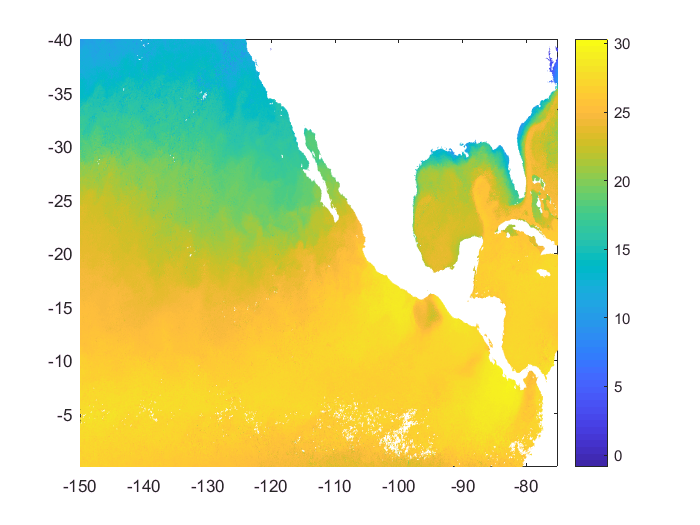

clear
close
clc

a = csvread('Datos\Oc\Imagenes\2003_1.csv');

lon = -1*a(2:end,3);
lat = a(1, 4:end);

a = a(2:end, 4:end);
a(a == 45.001) = NaN;

figure()
pcolor(lat, lon, a), shading interp, axis ij, colorbar

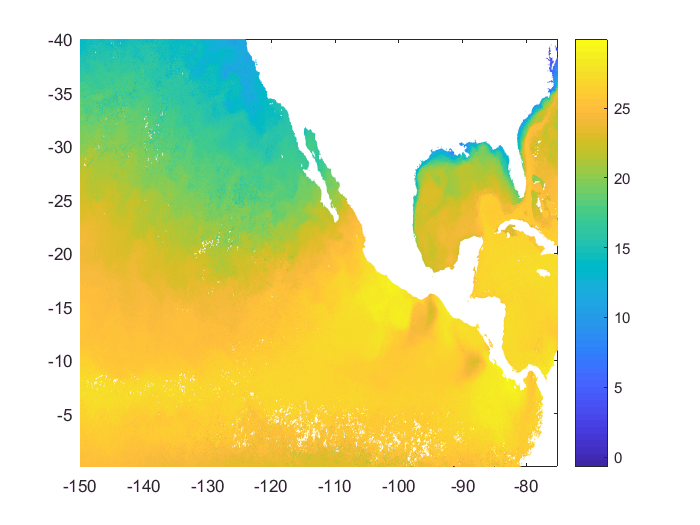

b = csvread('Datos\Oc\Imagenes\2014_1.csv');

lon = -1*b(2:end,3);
lat = b(1, 4:end);

b = b(2:end, 4:end);
b(b == 45.001) = NaN;

figure()
pcolor(lat, lon, b), shading interp, axis ij, colorbar

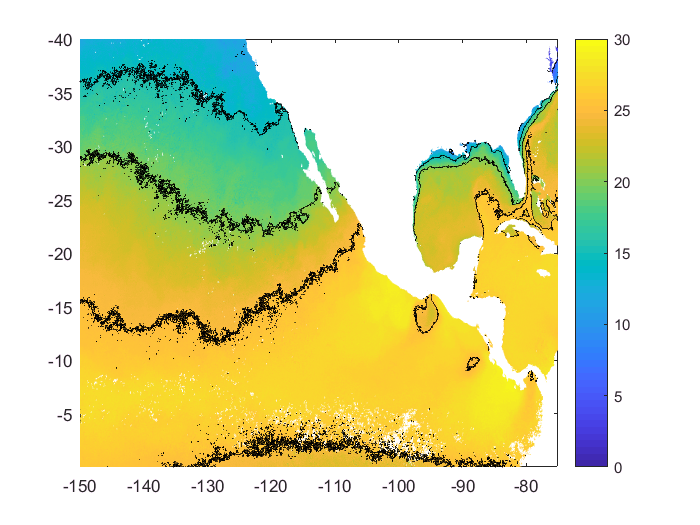

c = (a+b)./2;

pcolor(lat, lon, c), shading interp, caxis([0 30]), axis ij, hold on, colorbar
contour(lat, lon, c, 'k')

## temporal

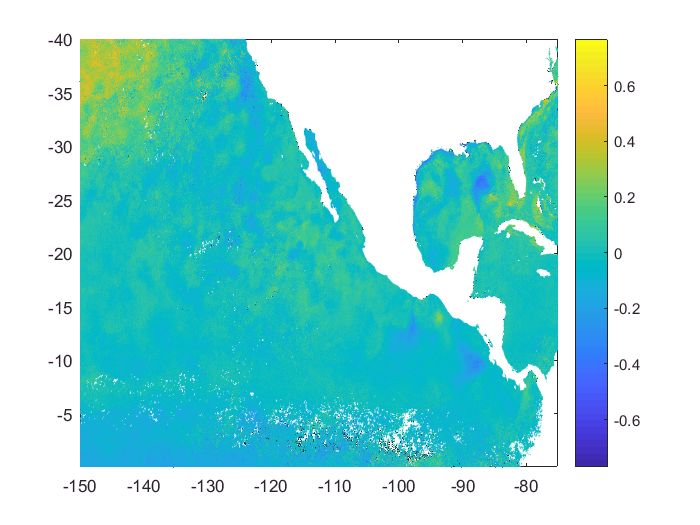

d = (b-a)/11;
pcolor(lat, lon, d), shading interp, caxis([min(min(d)), max(max(d))]), axis ij, hold on, colorbar

## gradient

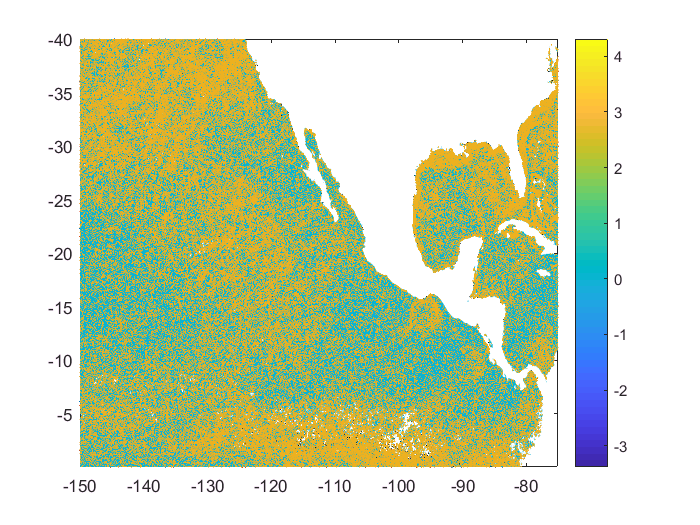

[x, y] = meshgrid(lat, lon);
[u, v] = gradient(c);

pcolor(lat, lon, v), shading interp, caxis([min(min(u+v)), max(max(u+v))]), axis ij, colorbar
quiver(x, y, u, v, 5)

## Climate velocity

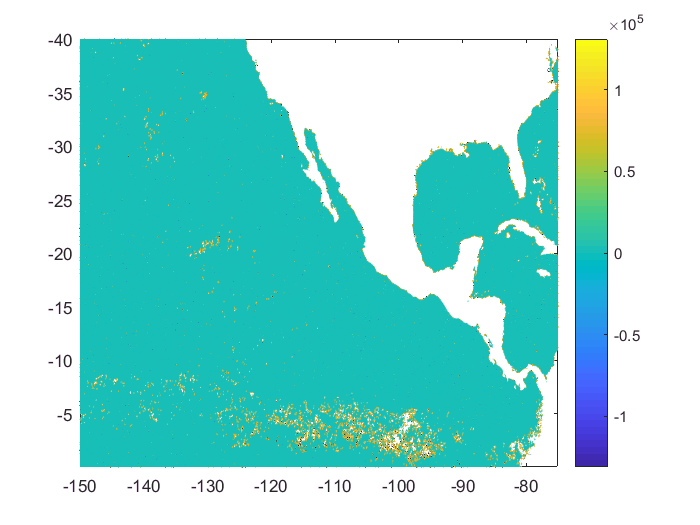

e = 2./(u+v);
e(abs(e) == Inf) = NaN;
e = sign(e).*abs(e).^(1/3);
pcolor(lat, lon, e), shading interp, caxis([min(min(e)), max(max(e))]), axis ij